# Model Definition

clear;
run Forward_Kinematics.m;
dhw = [0.09,pi/2,0.595,0]

dhw =     0.0900    1.5708    0.5950         0


dhparams = [0,-pi/2,l1,0;0,pi/2,0,pi/2;0,0,(l2+l3),-pi/2;0,pi/2,l4,0;l5,pi/2,0,pi/2];

## Robot Main Structure

Walle = robotics.RigidBodyTree()

Walle =   RigidBodyTree with properties:

     NumBodies: 0
        Bodies: {1×0 cell}
          Base: [1×1 robotics.RigidBody]
     BodyNames: {1×0 cell}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'struct'


## Create Links


%Link1
link1 = robotics.RigidBody('Shoulder')

link1 =   RigidBody with properties:

            Name: 'Shoulder'
           Joint: [1×1 robotics.Joint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}


j1 = robotics.Joint('j1','revolute')

j1 =   Joint with properties:

                      Type: 'revolute'
                      Name: 'j1'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


j1.PositionLimits = [-pi/3 pi];
%j1.HomePosition = 
setFixedTransform(j1,double(T01));
j1.JointAxis = double(T01(1:3,3)');

link1.Joint = j1;

%Link2
link2 = robotics.RigidBody('Arm')

link2 =   RigidBody with properties:

            Name: 'Arm'
           Joint: [1×1 robotics.Joint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}


j2 = robotics.Joint('j2','revolute')

j2 =   Joint with properties:

                      Type: 'revolute'
                      Name: 'j2'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


j2.PositionLimits = [-pi 0];
setFixedTransform(j2,double(T12));
j2.JointAxis = double(T12(1:3,3)');

link2.Joint = j2;

%Link3
link3 = robotics.RigidBody('Elbow')

link3 =   RigidBody with properties:

            Name: 'Elbow'
           Joint: [1×1 robotics.Joint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}


j3 = robotics.Joint('j3','prismatic')

j3 =   Joint with properties:

                      Type: 'prismatic'
                      Name: 'j3'
                 JointAxis: [0 0 1]
            PositionLimits: [-0.5000 0.5000]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


j3.PositionLimits = [0 0.5];
setFixedTransform(j3,double(T23));
j3.JointAxis = double(T23(1:3,3)');


link3.Joint = j3;

%Link4
link4 = robotics.RigidBody('Wrist')

link4 =   RigidBody with properties:

            Name: 'Wrist'
           Joint: [1×1 robotics.Joint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}


j4 = robotics.Joint('j4','revolute')

j4 =   Joint with properties:

                      Type: 'revolute'
                      Name: 'j4'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


j4.PositionLimits = deg2rad([-180,180]);
setFixedTransform(j4,double(T34));
j4.JointAxis = double(T34(1:3,3)');

link4.Joint = j4;

%Link5
link5 = robotics.RigidBody('Paddle')

link5 =   RigidBody with properties:

            Name: 'Paddle'
           Joint: [1×1 robotics.Joint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}


j5 = robotics.Joint('j5','revolute')

j5 =   Joint with properties:

                      Type: 'revolute'
                      Name: 'j5'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


j5.PositionLimits = [-(2*pi/3) (2*pi/3)];
setFixedTransform(j5,double(T4n));
j5.JointAxis = double(T4n(1:3,3)');

link5.Joint = j5;

addBody(Walle,link1,'base');
addBody(Walle,link2,'Shoulder');
addBody(Walle,link3,'Arm');
addBody(Walle,link4,'Elbow');
addBody(Walle,link5,'Wrist');

showdetails(Walle);

--------------------
Robot: (5 bodies)

 Idx       Body Name   Joint Name   Joint Type       Parent Name(Idx)   Children Name(s)
 ---       ---------   ----------   ----------       ----------------   ----------------
   1        Shoulder           j1     revolute                base(0)   Arm(2)  
   2             Arm           j2     revolute            Shoulder(1)   Elbow(3)  
   3           Elbow           j3    prismatic                 Arm(2)   Wrist(4)  
   4           Wrist           j4     revolute               Elbow(3)   Paddle(5)  
   5          Paddle           j5     revolute               Wrist(4)   
--------------------


## Show Robot in Home Config

Qhome = Walle.homeConfiguration

Qhome = 1×5 struct array with fields:
    JointName
    JointPosition


qHome = [Qhome.JointPosition]

qHome =      0     0     0     0     0


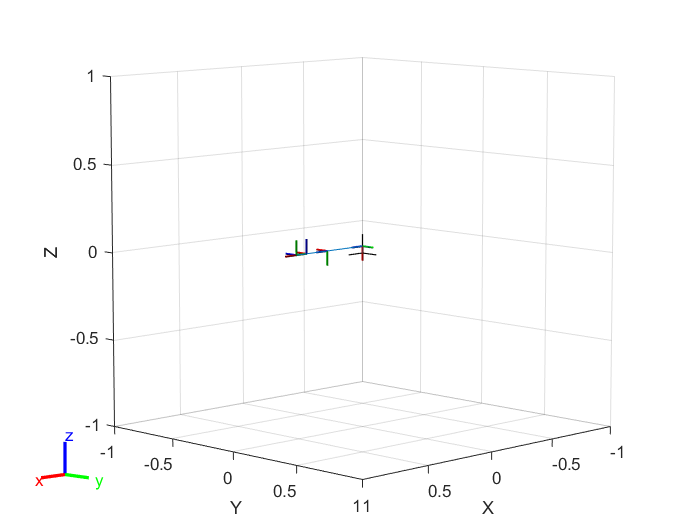

figure;
show(Walle,Qhome);


T = getTransform(Walle, Qhome,'Paddle')

T =     1.0000         0         0    0.5175
         0         0   -1.0000         0
         0    1.0000         0    0.0392
         0         0         0    1.0000


## Compute Inverse Kinematics

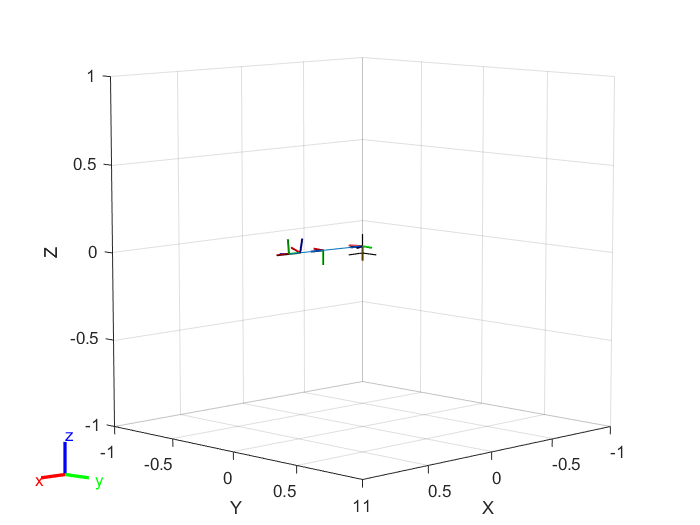

ik = robotics.InverseKinematics('RigidBodyTree',Walle);
weights = [1 1 1 1 1 1];
ikInitialGuess = Walle.homeConfiguration;
q = [pi/2,-pi/2,0.2,pi/2,pi/2];
ikInitialGuess = arrayfun(@(x,y) setfield(x,'JointPosition',y), ikInitialGuess ,q);
Tee = double(subs((T0n),{t1,t2,d3,t4,t5},{0,-pi/2`,0,0,0}));
%Tee = double(T0n)
[QSol,SolInfo] = step(ik,'Paddle',Tee,weights,ikInitialGuess);

figure;
show(Walle,QSol);

qSol = [QSol.JointPosition]'

qSol =     1.1566
   -1.0326
         0
    0.2376
    0.3615



%Verification
Tik = getTransform(Walle,QSol,'Paddle')

Tik =     0.9923   -0.0153   -0.1227    0.5135
   -0.1236   -0.1227   -0.9847   -0.0640
         0    0.9923   -0.1236    0.0392
         0         0         0    1.0000


%Treq = getTransform(Walle,,'Paddle')